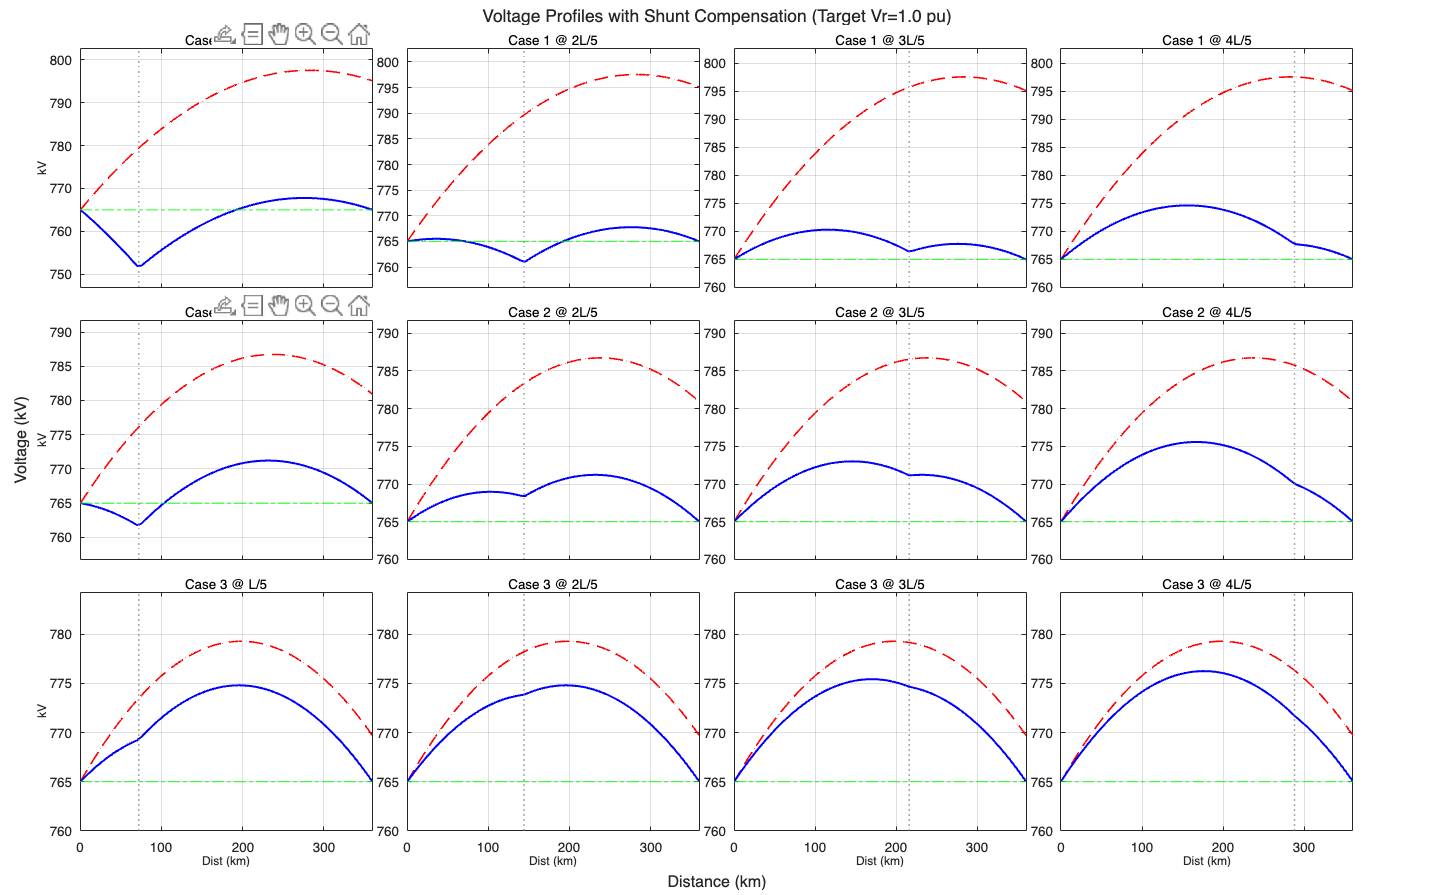

 LOAD CASE 1: 311.3 MW (PF=0.92)


Loc    | Strategy 1 (Target Vr=1.0) | Currents     | Strategy 2 (Target Vsh=1.0)


x      | B(uS)   Q(MVar) Vr(pu)   | Is(kA) Ir(kA) | B(uS)   Q(MVar) Vr(pu) 


-----------------------------------------------------------------------------------------------------


L/5    | -1312.7 -741.3  1.0000   | 0.585 0.442 | -665.1  -389.2  1.0191 
2L/5   | -650.2  -376.5  1.0000   | 0.414 0.442 | -555.1  -324.8  1.0056 
3L/5   | -432.6  -254.1  1.0000   | 0.472 0.442 | -453.2  -265.2  0.9982 
4L/5   | -326.2  -192.3  1.0000   | 0.520 0.442 | -357.1  -209.0  0.9964 


 LOAD CASE 2: 456.6 MW (PF=0.92)


Loc    | Strategy 1 (Target Vr=1.0) | Currents     | Strategy 2 (Target Vsh=1.0)


x      | B(uS)   Q(MVar) Vr(pu)   | Is(kA) Ir(kA) | B(uS)   Q(MVar) Vr(pu) 


-----------------------------------------------------------------------------------------------------


L/5    | -667.9  -387.5  1.0000   | 0.599 0.649 | -510.8  -298.9  1.0048 
2L/5   | -332.2  -196.1  1.0000   | 0.630 0.649 | -407.4  -238.4  0.9954 
3L/5   | -221.9  -132.0  1.0000   | 0.663 0.649 | -312.4  -182.8  0.9917 
4L/5   | -168.0  -99.6   1.0000   | 0.683 0.649 | -222.9  -130.5  0.9934 


 LOAD CASE 3: 561.3 MW (PF=0.92)


Loc    | Strategy 1 (Target Vr=1.0) | Currents     | Strategy 2 (Target Vsh=1.0)


x      | B(uS)   Q(MVar) Vr(pu)   | Is(kA) Ir(kA) | B(uS)   Q(MVar) Vr(pu) 


-----------------------------------------------------------------------------------------------------


L/5    | -190.8  -112.9  1.0000   | 0.767 0.798 | -386.6  -226.2  0.9938 
2L/5   | -95.2   -57.0   1.0000   | 0.792 0.798 | -290.3  -169.9  0.9876 
3L/5   | -63.8   -38.3   1.0000   | 0.801 0.798 | -202.3  -118.4  0.9869 
4L/5   | -48.5   -28.9   1.0000   | 0.807 0.798 | -119.5  -69.9   0.9911 


% Shunt Compensation
% Energy Systems Analysis - Dr. Fotuhi-Firuzabad
% Student: Vahid Hamzeh - 402101577

clc; clear; close all;

% System Parameters
V_base_LL = 765;      
V_base = 765e3;       
L_total = 360;       
f = 50;              

% Line Parameters
R_prime = 0;          
X_prime = 0.38;       
B_prime = 2.8e-6;    

% Calculated Parameters
z = R_prime + 1j*X_prime;
y = 0 + 1j*B_prime;
gamma = sqrt(z*y);    
Zc = sqrt(z/y);       
beta = imag(gamma);   

% Load Cases
Load_Cases_MW = [311.3, 456.6, 561.3];
PF = 0.92;

% Shunt Locations
Loc_fractions = [0.2, 0.4, 0.6, 0.8]; 
Loc_km = Loc_fractions * L_total; 
Loc_labels = {'L/5', '2L/5', '3L/5', '4L/5'};

Vs_target_mag = 1.0; 

% Setup Figure
fig = figure('Name', 'Voltage Profiles Grid', 'Color', 'w', 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);
t = tiledlayout(3, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Voltage Profiles with Shunt Compensation (Target Vr=1.0 pu)');
xlabel(t, 'Distance (km)');
ylabel(t, 'Voltage (kV)');

for i_case = 1:3
    P_MW = Load_Cases_MW(i_case);
    Q_Mvar = P_MW * tan(acos(PF));
    
    % --- Print Header for Table ---
    fprintf('\n=====================================================================================================\n');
    fprintf(' LOAD CASE %d: %.1f MW (PF=0.92)\n', i_case, P_MW);
    fprintf('=====================================================================================================\n');
    fprintf('%-6s | %-25s | %-12s | %-25s\n', 'Loc', 'Strategy 1 (Target Vr=1.0)', 'Currents', 'Strategy 2 (Target Vsh=1.0)');
    fprintf('%-6s | %-7s %-7s %-8s | %-5s %-5s | %-7s %-7s %-7s\n', ...
            'x', 'B(uS)', 'Q(MVar)', 'Vr(pu)', 'Is(kA)', 'Ir(kA)', 'B(uS)', 'Q(MVar)', 'Vr(pu)');
    fprintf('-----------------------------------------------------------------------------------------------------\n');

    [dist_un, V_un_pu, ~, ~] = get_profile(L_total, -1, 0, Zc, beta, P_MW, Q_Mvar, V_base, Vs_target_mag);
    V_un_kV = V_un_pu * V_base_LL; 
    
    for i_loc = 1:4
        x_sh = Loc_km(i_loc);
        
        % Target Vr = 1.0 
        fun1 = @(b) solve_error_Vr(b, x_sh, L_total, Zc, beta, P_MW, Q_Mvar, V_base, Vs_target_mag, 1.0);
        B1 = fzero(fun1, 0);
        
        [dist, V_comp_pu, Vsh1, Ivec] = get_profile(L_total, x_sh, B1, Zc, beta, P_MW, Q_Mvar, V_base, Vs_target_mag);
        V_comp_kV = V_comp_pu * V_base_LL;
        
        Q1 = (Vsh1 * V_base)^2 * B1 / 1e6; 
        Is_kA = Ivec(1);
        Ir_kA = Ivec(end);
        
        % Target V_shunt = 1.0 
        fun2 = @(b) solve_error_Vsh(b, x_sh, L_total, Zc, beta, P_MW, Q_Mvar, V_base, Vs_target_mag, 1.0);
        try
            B2 = fzero(fun2, 0);
            [~, Vvec2, ~, ~] = get_profile(L_total, x_sh, B2, Zc, beta, P_MW, Q_Mvar, V_base, Vs_target_mag);
            Vr2 = Vvec2(end);
            Q2 = (1.0 * V_base)^2 * B2 / 1e6;
        catch
            B2 = NaN; Q2 = NaN; Vr2 = NaN;
        end
        
        fprintf('%-6s | %-7.1f %-7.1f %-8.4f | %-5.3f %-5.3f | %-7.1f %-7.1f %-7.4f\n', ...
            Loc_labels{i_loc}, B1*1e6, Q1, V_comp_pu(end), Is_kA, Ir_kA, B2*1e6, Q2, Vr2);

        nexttile;
        hold on; box on; grid on;
        
        plot(dist, V_un_kV, 'r--', 'LineWidth', 1.2);
        plot(dist, V_comp_kV, 'b-', 'LineWidth', 1.5);
        yline(765, 'g-.', 'LineWidth', 1);
        xline(x_sh, 'Color', [0.5 0.5 0.5], 'LineStyle', ':', 'LineWidth', 1.2);
        
        % Visual Adjustments
        xlim([0 L_total]);
        ylim([min([V_comp_kV V_un_kV])-5, max([V_comp_kV V_un_kV])+5]);
        
        % Subplot Title
        title(sprintf('Case %d @ %s', i_case, Loc_labels{i_loc}), 'FontSize', 10, 'FontWeight', 'normal');
        
        if i_case == 3
             xlabel('Dist (km)', 'FontSize', 9);
        else
             set(gca, 'XTickLabel', []); 
        end
        if i_loc == 1
             ylabel('kV', 'FontSize', 9);
        end
    end
end

function err = solve_error_Vr(Bsh, x_sh, L, Zc, beta, P, Q, Vbase, Vs_set, Target_Vr)
    [~, Vvec, ~, ~] = get_profile(L, x_sh, Bsh, Zc, beta, P, Q, Vbase, Vs_set);
    err = Vvec(end) - Target_Vr;
end

function err = solve_error_Vsh(Bsh, x_sh, L, Zc, beta, P, Q, Vbase, Vs_set, Target_Vsh)
    [~, ~, Vsh, ~] = get_profile(L, x_sh, Bsh, Zc, beta, P, Q, Vbase, Vs_set);
    err = Vsh - Target_Vsh;
end

function [dist, V_mag, V_sh_mag, I_mag] = get_profile(L, x_sh, Bsh, Zc, beta, P, Q, Vbase, Vs_target)
    S_load = (P + 1j*Q) * 1e6;
    
    if x_sh < 0 
        T_eq = [cos(beta*L), 1j*Zc*sin(beta*L); 1j/Zc*sin(beta*L), cos(beta*L)];
    else
        A1 = cos(beta*x_sh); B1 = 1j*Zc*sin(beta*x_sh);
        C1 = 1j/Zc*sin(beta*x_sh); D1 = A1;
        T1 = [A1 B1; C1 D1];
        Tsh = [1 0; 1j*Bsh 1];
        len2 = L - x_sh;
        A2 = cos(beta*len2); B2 = 1j*Zc*sin(beta*len2);
        C2 = 1j/Zc*sin(beta*len2); D2 = A2;
        T2 = [A2 B2; C2 D2];
        T_eq = T1 * Tsh * T2;
    end
    
    A = T_eq(1,1); B = T_eq(1,2);
    
    options = optimoptions('fsolve','Display','off');
    Vr_complex = fsolve(@(v) abs(A*v + B*conj(S_load/v)) - Vs_target*Vbase, Vbase, options);
    Ir_complex = conj(S_load / Vr_complex);
    
    dist_from_r = 0:5:L; 
    dist = L - dist_from_r; 
    
    V_mag = zeros(size(dist));
    I_mag = zeros(size(dist));
    
    for k = 1:length(dist_from_r)
        y = dist_from_r(k); 
        
        if x_sh < 0 || y < (L - x_sh)
            Ay = cos(beta*y); By = 1j*Zc*sin(beta*y);
            Cy = 1j/Zc*sin(beta*y); Dy = Ay;
            Vy = Ay*Vr_complex + By*Ir_complex;
            Iy = Cy*Vr_complex + Dy*Ir_complex;
        else
            len2 = L - x_sh;
            A2 = cos(beta*len2); B2 = 1j*Zc*sin(beta*len2);
            C2 = 1j/Zc*sin(beta*len2); D2 = A2;
            V_sh_loadside = A2*Vr_complex + B2*Ir_complex;
            I_sh_loadside = C2*Vr_complex + D2*Ir_complex;
            I_sh_sourceside = I_sh_loadside + 1j*Bsh*V_sh_loadside;
            V_sh_sourceside = V_sh_loadside;
            
            len_rem = y - len2;
            Ax = cos(beta*len_rem); Bx = 1j*Zc*sin(beta*len_rem);
            Cx = 1j/Zc*sin(beta*len_rem); Dx = Ax;
            Vy = Ax*V_sh_sourceside + Bx*I_sh_sourceside;
            Iy = Cx*V_sh_sourceside + Dx*I_sh_sourceside;
        end
        
        V_mag(k) = abs(Vy)/Vbase;
        I_mag(k) = abs(Iy)/1000;
        
        if abs((L-y) - x_sh) < 2.6 
            V_sh_mag = V_mag(k);
        end
    end
    
    dist = fliplr(dist);
    V_mag = fliplr(V_mag);
    I_mag = fliplr(I_mag);
    
    if exist('V_sh_sourceside', 'var')
        V_sh_mag = abs(V_sh_sourceside)/Vbase;
    else
        V_sh_mag = V_mag(end);
    end
end